## Newton - Euler Algorithm

### 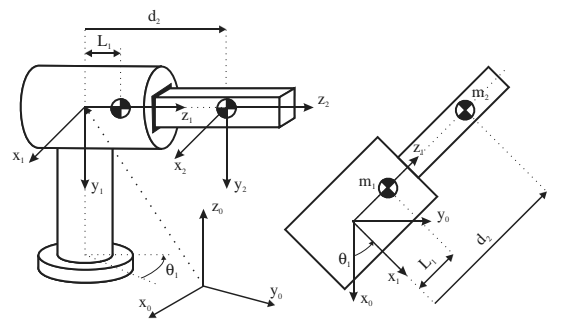

### Establish initial conditions

where:

- pii = Vector that joins S(i-1) with Si expressed Si as: [ai, di*sin(alphai), di*cos(alphai)]

- sii = Coodinates of limb i's center of mass with respect to Si

- Iii = Inertia matrix of limb i expressed paralel to Si and with it's origin at the center of mass

syms g l1 d2 d2_dot d2_ddot theta1 theta1_dot theta1_ddot m1 m2

% for S0 (starting from rest)
w00 = [0 0 0].';
w00_dot = [0 0 0].';
v00 = [0 0 0].';
v00_dot = [0 0 g].';
z0 = [0 0 1].';

p11 = [0 0 0].';
s11 = [0 0 l1].';
p22 = [0 0 d2].';
s22 = [0 0 0].';
I11 = zeros(3,3);
I22 = zeros(3,3);

### Solving for rotation matrixes

where:

- R(i-1)i = [ cos(thetai), -cos(alphai)*sin(thetai), sin(alphai)*sin(thetai); ...

                            sin(thetai), cos(alphai)*cos(thetai), -sin(alphai)*cos(thetai); ...

                            0, sin(alphai), cos(alphai) ]

R01 = [cos(theta1) 0 -sin(theta1); sin(theta1) 0 cos(theta1); 0 -1 0]

$$R01 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right)\\ 0 & -1 & 0 \end{array}\right)$$

R10 = R01.'

$$R10 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & 0\\ 0 & 0 & -1\\ -\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 \end{array}\right)$$

R12 = eye(3)

R12 =      1     0     0
     0     1     0
     0     0     1


R21 = R12.'

R21 =      1     0     0
     0     1     0
     0     0     1


R02 = R01 * R12

$$R02 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right)\\ 0 & -1 & 0 \end{array}\right)$$

R20 = R02.'

$$R20 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & 0\\ 0 & 0 & -1\\ -\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 \end{array}\right)$$

### Solving for angular velocity

where:

- wii = Ri(i-1) * [ w(i-1)(i-1) + z0 * qi_dot]     if limb i is rotational

- wii = Ri(i-1) * w(i-1)(i-1)     if limb i is traslational

w11 = R10 * (w00 + z0*theta1_dot)

$$w11 = \left(\begin{array}{c} 0\\ -\theta_{\dot{1}}\\ 0 \end{array}\right)$$

w22 = R21 * w11

$$w22 = \left(\begin{array}{c} 0\\ -\theta_{\dot{1}}\\ 0 \end{array}\right)$$

### Solving for angular acceleration

where:

- wii_dot = Ri(i-1) * [ w(i-1)(i-1)_dot + z0 * qi_ddot] + w(i-1)(i-1) x z0 * qi_dot     if limb i is rotational

- wii_dot = Ri(i-1) * w(i-1)(i-1)_dot     if limb i is traslational

w11_dot = R10 * (w00_dot + z0 * theta1_ddot) + cross(w00, z0 * theta1_dot)

$$w11\_dot = \left(\begin{array}{c} 0\\ -\theta_{\ddot{1}}\\ 0 \end{array}\right)$$

w22_dot = R21 * w11_dot

$$w22\_dot = \left(\begin{array}{c} 0\\ -\theta_{\ddot{1}}\\ 0 \end{array}\right)$$

### Solving for linear acceleration

where:

- vii_dot = wii_dot x pii + wii x [ wii x pii ] + Ri(i-1) * v(i-1)(i-1)_dot     if limb i is rotational

- vii_dot = Ri(i-1) * [ z0 * qi_ddot + v(i-1)(i-1)_dot ] + wii x pii + 2 * wii x Ri(i-1) * z0 * qi_dot + wii x [ wii x pii ]     if limb is traslational

v11_dot = cross(w11_dot, p11) + cross(w11, cross(w11, p11)) + R10 * v00_dot

$$v11\_dot = \left(\begin{array}{c} 0\\ -g\\ 0 \end{array}\right)$$

v22_dot = R21 * (z0 * d2_ddot + v11_dot) + cross(w22, p22) + cross((2 * w22), (R21 * z0 * d2_dot)) + cross(w22, cross(w22, p22))

$$v22\_dot = \left(\begin{array}{c} -d_{2}\,\theta_{\dot{1}}-2\,d_{\dot{2}}\,\theta_{\dot{1}}\\ -g\\ d_{\ddot{2}}-d_{2}\,{\theta_{\dot{1}}}^{2} \end{array}\right)$$

### Solving for center of gravity linear acceleration

where:

- aii = wii_dot x sii + wii x [ wii x sii ] + vii_dot

a11 = cross(w11_dot, s11) + cross(w11, cross(w11, s11)) + v11_dot

$$a11 = \left(\begin{array}{c} -l_{1}\,\theta_{\ddot{1}}\\ -g\\ -l_{1}\,{\theta_{\dot{1}}}^{2} \end{array}\right)$$

a22 = cross(w22_dot, s22) + cross(w22, cross(w22, s22)) + v22_dot

$$a22 = \left(\begin{array}{c} -d_{2}\,\theta_{\dot{1}}-2\,d_{\dot{2}}\,\theta_{\dot{1}}\\ -g\\ d_{\ddot{2}}-d_{2}\,{\theta_{\dot{1}}}^{2} \end{array}\right)$$

### Solving for forces

where:

- fii = Ri(i-1) * f(i+1)(i+1) + mi * aii

f33 = [0 0 0].';
R23 = eye(3);
R32 = R23.';

f22 = R23 * f33 + m2 * a22

$$f22 = \left(\begin{array}{c} -m_{2}\,\left(d_{2}\,\theta_{\dot{1}}+2\,d_{\dot{2}}\,\theta_{\dot{1}}\right)\\ -g\,m_{2}\\ m_{2}\,\left(d_{\ddot{2}}-d_{2}\,{\theta_{\dot{1}}}^{2}\right) \end{array}\right)$$

f11 = R12 * f22 + m1 * a11

$$f11 = \left(\begin{array}{c} -m_{2}\,\left(d_{2}\,\theta_{\dot{1}}+2\,d_{\dot{2}}\,\theta_{\dot{1}}\right)-l_{1}\,m_{1}\,\theta_{\ddot{1}}\\ -g\,m_{1}-g\,m_{2}\\ m_{2}\,\left(d_{\ddot{2}}-d_{2}\,{\theta_{\dot{1}}}^{2}\right)-l_{1}\,m_{1}\,{\theta_{\dot{1}}}^{2} \end{array}\right)$$

### Solving for torques

where:

- nii = Ri(i-1) * [ n(i+1)(i+1) + [ R(i+1)i * pii ] x f(i+1)(i+1) ] + [ pii + sii ] x mi * aii + Iii * wii + wii x [ Iii * wii ]

n33 = [0 0 0].';

n22 = R23 * (n33 + cross((R32 * p22), f33)) + cross((p22 + s22), (m2 * a22)) + I22 * w22_dot + cross(w22, (I22 * w22))

$$n22 = \left(\begin{array}{c} d_{2}\,g\,m_{2}\\ -d_{2}\,m_{2}\,\left(d_{2}\,\theta_{\dot{1}}+2\,d_{\dot{2}}\,\theta_{\dot{1}}\right)\\ 0 \end{array}\right)$$

n11 = R12 * (n22 + cross((R21 * p11), f22)) + cross((p11 + s11), (m1 * a11)) + I11 * w11_dot + cross(w11, (I11 * w11))

$$n11 = \left(\begin{array}{c} d_{2}\,g\,m_{2}+g\,l_{1}\,m_{1}\\ -m_{1}\,\theta_{\ddot{1}}\,{l_{1}}^{2}-d_{2}\,m_{2}\,\left(d_{2}\,\theta_{\dot{1}}+2\,d_{\dot{2}}\,\theta_{\dot{1}}\right)\\ 0 \end{array}\right)$$

### Obtaining force or torque applied

where:

- taui = nii^T * Ri(i-1) * z0     if limb i is rotational

- taui = fii^T * Ri(i-1) * z0     if limb i is traslational

tau1 = n11.' * R10 * z0        % Torque appplied at limb 1

$$tau1 = m_{1}\,\theta_{\ddot{1}}\,{l_{1}}^{2}+d_{2}\,m_{2}\,\left(d_{2}\,\theta_{\dot{1}}+2\,d_{\dot{2}}\,\theta_{\dot{1}}\right)$$

tau2 = f22.' * R21 * z0        % Forces applied at limb 2

$$tau2 = m_{2}\,\left(d_{\ddot{2}}-d_{2}\,{\theta_{\dot{1}}}^{2}\right)$$